%Roberto Enriquez Gomez     A01252515

% Definición del problema
q1 = 3e-6; 
q2 = -5e-6; 
d = 0.5; 
k = 8.99e9; 

% Función de la ecuación cuadrática
f = @(x) k*q1./x.^2 + k*q2./(d-x).^2;

% Derivada de la función
df = @(x) -2*k*q1./x.^3 + 2*k*q2./(d-x).^3;

% Valor inicial para el método de Newton-Raphson
x0 = 0.1;

% Método de Newton-Raphson para encontrar la raíz
tolerance = 1e-4; 
max_iterations = 1000; 
iter = 0; 

while abs(f(x0)) > tolerance && iter < max_iterations
    iter = iter + 1;
    x0 = x0 - f(x0)/df(x0);
end

% Imprime la solución encontrada
fprintf('La carga prueba debe colocarse en x = %.4f metros\n', x0);

La carga prueba debe colocarse en x = 0.2182 metros


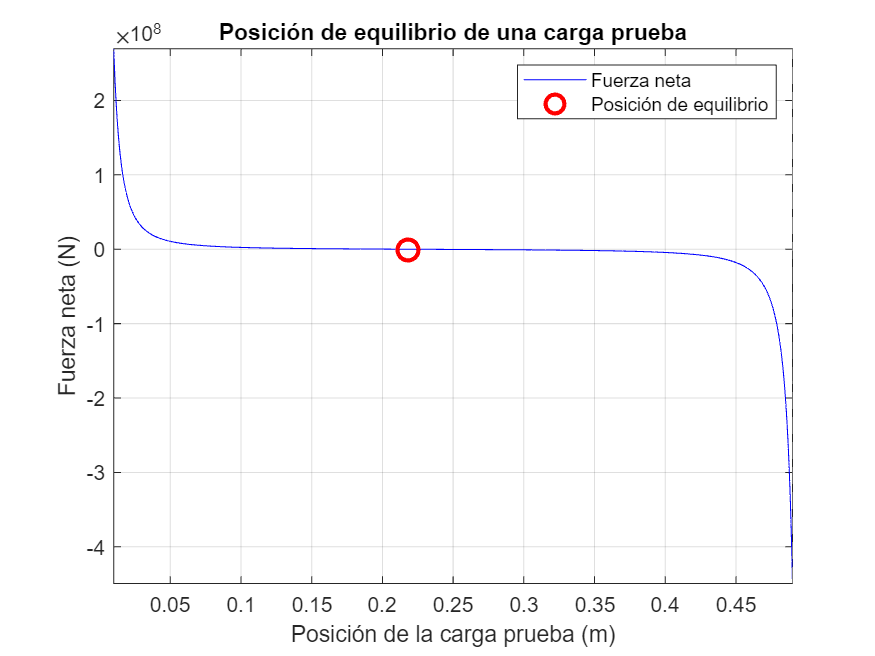


% Grafica la función
figure;
fplot(f, [0.01, 0.49], '-b');
hold on;
plot(x0, f(x0), 'or', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Posición de la carga prueba (m)');
ylabel('Fuerza neta (N)');
title('Posición de equilibrio de una carga prueba');
grid on;
legend('Fuerza neta', 'Posición de equilibrio');

% El equilibrio de la carga prueba en un arreglo de dos cargas sólo es posible en la región entre 
% las dos cargas. La magnitud y signo de la carga prueba necesaria para lograr el equilibrio se puede
% encontrar sumando vectorialmente las fuerzas eléctricas individuales debido a cada carga en el 
% arreglo. Si la carga prueba tiene una carga positiva, será atraída por la carga negativa y repelida 
% por la carga positiva. Si la carga prueba tiene una carga negativa, será atraída por la carga 
% positiva y repelida por la carga negativa. La magnitud de la carga prueba necesaria para lograr el 
% equilibrio dependerá de la distancia entre la carga prueba y las dos cargas en el arreglo, y 
% deberá tener una carga negativa para equilibrar la carga positiva en el origen y una carga positiva 
% para equilibrar la carga negativa en (0.5).